## **Simon's Solution**


clear all
syms x(t) y(t) theta(t) f(z) Ff(t) N(t) 
%Set paramters. 
m=1; r=1; g=9.81;

tspan=[0,10];
x0=1; theta0=0; dx0=0;

%MOI of disc about COM. 
IG=1/2*m*r^2;

%Position of COM.
rG=[x(t);y(t)];

phi=pi/6;

%Simon's equations. 
eq1=m*diff(rG,2)==[Ff*cos(phi) - N*sin(phi); Ff*sin(phi)+N*cos(phi)-m*g]

$$eq1(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{\sqrt{3}\,\mathrm{Ff}\left(t\right)}{2}-\frac{N\left(t\right)}{2}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{\mathrm{Ff}\left(t\right)}{2}+\frac{\sqrt{3}\,N\left(t\right)}{2}-\frac{981}{100} \end{array}\right)$$

eq2=IG*diff(theta,2)==Ff*r

$$eq2(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}=\mathrm{Ff}\left(t\right)$$


y0=@(x0) (x0+r*sin(phi))/cos(phi)*sin(phi)+r*cos(phi)

y0 = function_handle with value:
    @(x0)(x0+r*sin(phi))/cos(phi)*sin(phi)+r*cos(phi)




eq3=diff(rG,t)==[-diff(theta)*r*cos(phi); -diff(theta)*r*sin(phi)]

$$eq3(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=-\frac{\sqrt{3}\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ \frac{\partial }{\partial t}y\left(t\right)=-\frac{\frac{\partial }{\partial t}\theta \left(t\right)}{2} \end{array}\right)$$

solnSimon=mechanicsAsDAE([eq1;eq2],[],eq3,tspan,[x==x0;diff(x)==dx0;y==y0(x0);theta==theta0],[],0)

The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Ff: 1.635000 Fft:0.000000
N: 8.495709 Nt:0.000000
theta: 0.000000 thetat:0.000000
x: 1.000000 xt:0.000000
y: 1.732051 yt:0.000000
Dthetat: 0.000000 Dthetatt:3.270000
Dxt: 0.000000 Dxtt:-2.831903
Dyt: 0.000000 Dytt:-1.635000


solnSimon = struct with fields:
          t: [29×1 double]
         Ff: [29×1 double]
          N: [29×1 double]
      theta: [29×1 double]
          x: [29×1 double]
          y: [29×1 double]
    Dthetat: [29×1 double]
        Dxt: [29×1 double]
        Dyt: [29×1 double]


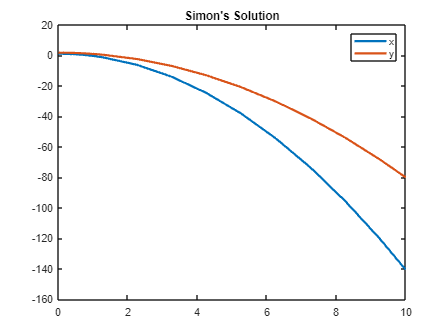

plot(solnSimon.t,solnSimon.x, solnSimon.t,solnSimon.y,'LineWidth',2); legend({'x','y'}); title("Simon's Solution");

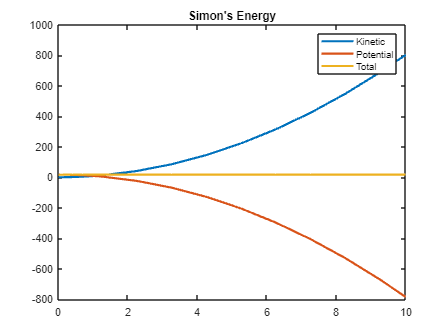

SimonKE=1/2*m*(solnSimon.Dxt.^2+solnSimon.Dyt.^2)+1/2*IG*solnSimon.Dthetat.^2;
SimonPE = m*solnSimon.y*g;
plot(solnSimon.t,SimonKE, solnSimon.t,SimonPE,solnSimon.t,SimonKE+SimonPE, 'LineWidth',2); legend({"Kinetic","Potential","Total"}); title("Simon's Energy")

## Joe's Solution

syms F1(t) F2(t) s f(z) cpx(t) cpy(t)

f(z)=tan(phi)*z;

alpha=r;

%Position of COM.
rG=[x(t);y(t)];

%Contact forces. 
F=[F1(t);F2(t)];

%Contact point
cp=[cpx(t);cpy(t)];

%COLM
eqJoe1=m*diff(rG,2)==F-m*[0;g]

$$eqJoe1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=F_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=F_{2}\left(t\right)-\frac{981}{100} \end{array}\right)$$


MFG=cross([cp-rG;0],[F;0]);
eqJoe2=IG*diff(theta,2)==MFG(3)

$$eqJoe2(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}=F_{2}\left(t\right)\,\left(\mathrm{cpx}\left(t\right)-x\left(t\right)\right)-F_{1}\left(t\right)\,\left(\mathrm{cpy}\left(t\right)-y\left(t\right)\right)$$

%The tangnential direction to the wire is
T=[1;diff(f)]/sqrt(1+diff(f)^2)

$$T(z) = \left(\begin{array}{c} \frac{\sqrt{3}}{2}\\ \frac{1}{2} \end{array}\right)$$

%The normal direction to the wire is
N=[-diff(f);1]/sqrt(1+diff(f)^2)

$$N(z) = \left(\begin{array}{c} -\frac{1}{2}\\ \frac{\sqrt{3}}{2} \end{array}\right)$$

%rG must be alpha from cp in the normal direction from (cpx,xpy).
eqJoe3=rG==[cpx;cpy]+alpha*N(cpx)

$$eqJoe3(t) = \left(\begin{array}{c} x\left(t\right)=\mathrm{cpx}\left(t\right)-\frac{1}{2}\\ y\left(t\right)=\mathrm{cpy}\left(t\right)+\frac{\sqrt{3}}{2} \end{array}\right)$$

%cp must be on the wire. 
eqJoe4=cpy==f(cpx)

$$eqJoe4(t) = \mathrm{cpy}\left(t\right)=\frac{\sqrt{3}\,\mathrm{cpx}\left(t\right)}{3}$$

%eq6=sqrt(diff(cpx)^2+diff(cpy)^2)==-sqrt(alpha^2*diff(theta)^2)
df=diff(f);
eqJoe5=diff(alpha*theta==-int(sqrt(1+(df(s)^2)),s,x0,cpx(t)))

$$eqJoe5(t) = \frac{\partial }{\partial t}\theta \left(t\right)=-\frac{2\,\sqrt{3}\,\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)}{3}$$

%Equations of motion
DEs=[eqJoe1;eqJoe2];

%I am unsure how to make the number of euqations vs constraints work out. 

positionConstraint=[eqJoe3;eqJoe4];

%Roll without slip condition. 
velocityConstraint=[eqJoe5];


solnJoe=mechanicsAsDAE(DEs,positionConstraint,velocityConstraint,tspan,[theta==theta0,x==x0,diff(x)==dx0],[],0)

The unknown functions (just the base functions, not derivatives) are: F1(t),F2(t),cpx(t),cpy(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
F1: -2.831903 F1t:0.000000
F2: 8.175000 F2t:0.000000
cpx: 1.500000 cpxt:0.000000
cpy: 0.866025 cpyt:0.000000
theta: 0.000000 thetat:0.000000
x: 1.000000 xt:0.000000
y: 1.732051 yt:0.000000
Dcpxt: 0.000000 Dcpxtt:-2.831903
Dcpyt: 0.000000 Dcpytt:-1.635000
Dthetat: 0.000000 Dthetatt:3.270000
Dxt: 0.000000 Dxtt:-2.831903
Dyt: 0.000000 Dytt:-1.635000


solnJoe = struct with fields:
          t: [29×1 double]
         F1: [29×1 double]
         F2: [29×1 double]
        cpx: [29×1 double]
        cpy: [29×1 double]
      theta: [29×1 double]
          x: [29×1 double]
          y: [29×1 double]
      Dcpxt: [29×1 double]
      Dcpyt: [29×1 double]
    Dthetat: [29×1 double]
        Dxt: [29×1 double]
        Dyt: [29×1 double]


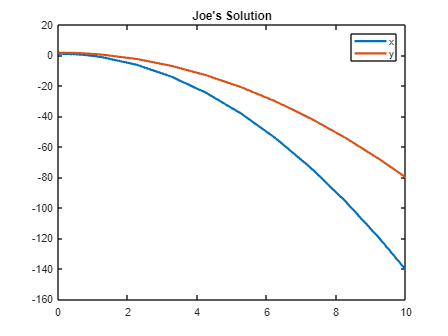

plot(solnJoe.t,solnJoe.x, solnJoe.t,solnJoe.y,'LineWidth',2); legend({'x','y'}); title("Joe's Solution");

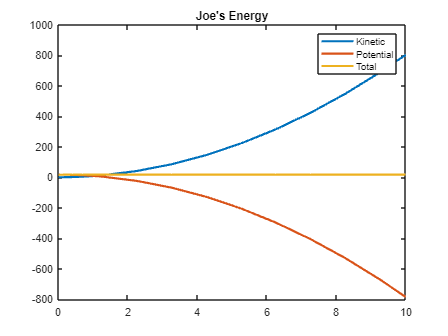

JoeKE=1/2*m*(solnJoe.Dxt.^2+solnJoe.Dyt.^2)+1/2*IG*solnJoe.Dthetat.^2;
JoePE = m*solnJoe.y*g;
plot(solnJoe.t,JoeKE, solnJoe.t,JoePE,solnJoe.t,JoeKE+JoePE, 'LineWidth',2); legend({"Kinetic","Potential","Total"}); title("Joe's Energy")